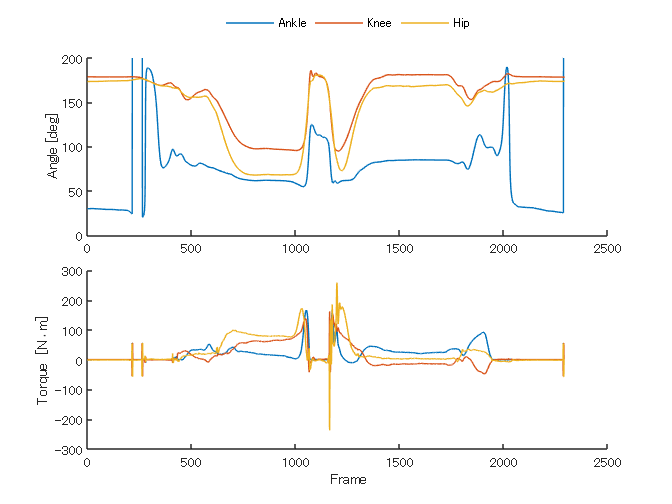

path = 'data\';

FP = read_forces([path, 'static1.forces']);
body_weight = mean(FP.grf(3,:)) / 9.8;

pos = read_TRC([path, 'SJ1.trc']);
FP = read_forces([path, 'SJ1.forces']);
pos = structfun(@(data) autoSmooth(data, 200), pos, UniformOutput=false);
[angle, torq] = get_angletorq(FP, pos, body_weight);
figure; til = tiledlayout(2, 1, TileSpacing='compact');
nexttile; hold on
plot(angle.ankle*180/pi)
plot(angle.knee*180/pi)
plot(angle.hip*180/pi)
ylabel('Angle [deg]')
ylim([0, 200])

nexttile; hold on
plot(torq.ankle)
plot(torq.knee)
plot(torq.hip)
ylabel('Torque [N\cdotm]')
xlabel('Frame')

leg = legend('Ankle', 'Knee', 'Hip', Location='layout', Orientation='horizontal', Box='off');
leg.Layout.Tile = 'north';